% Simulation Constants
ball_mass = 2.7;      % grams
ball_radius = 20.25;  % mm
ball_rot_inertia = 2/3*ball_mass*ball_radius^2; % g mm^2
table_restitution = 0.77; % 
net_restitution = 0.5;
drag = 2.7;           % mN/(mm/s)
rot_drag = 350.0;     % mN mm/[rad/s]
magnus = 0.01;       % mN/(mm/s^2)
table_friction = 0.25;% proportion of the angular velocity transformed onto linear velocity on bounce
table_length = 2740;  % mm
table_width = 1525;   % mm
table_height = 760;   % mm
net_height = 152.5;   % mm
net_extra = 180;      % mm
g = 9800;             % mm/s^2
animate = true;
plot_period = 5;
yaw = -45;
pitch = 30.5

pitch = 30.5000

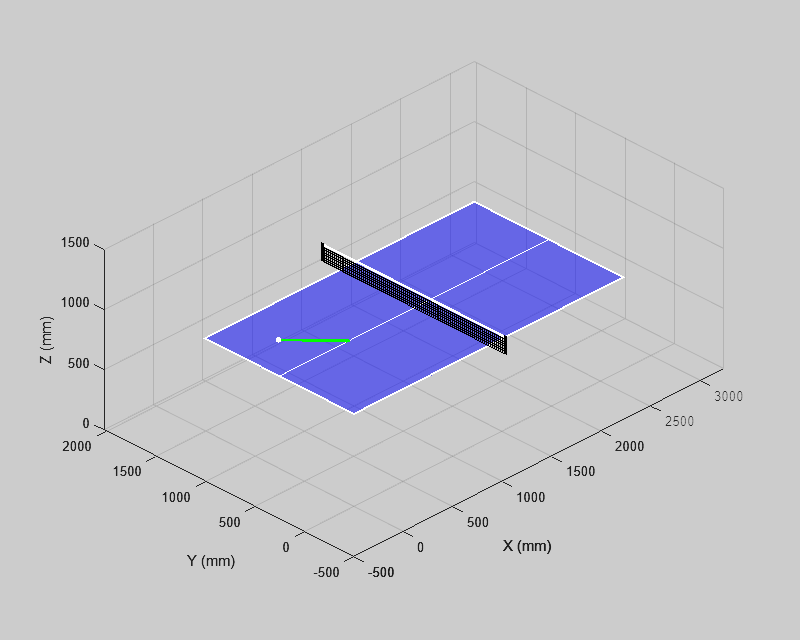

dt = 0.005;
t = 0:dt:1;
x = zeros(3,length(t));
v = zeros(3,length(t));
a = zeros(3,length(t));
theta = zeros(3,length(t));
omega = zeros(3,length(t));
alpha = zeros(3,length(t));
% Initial Conditions
x(:,1) = [0; table_width*4/8; table_height+2*net_height];
v(:,1) = [7000; 0; -3000];           % [7000; 0; -1500] short backspin service
omega(:,1) = [0; 0; 0]*2*pi;      % [0; -75*2*pi; 0] short backspin service
fig = figure(); 
fig.Position(1:2) = [400, 400];
fig.Position(3:4) = [800, 640];
plotTable(x(:,1),v(:,1),a(:,1),theta(:,1),omega(:,1),alpha(:,1), yaw, pitch)

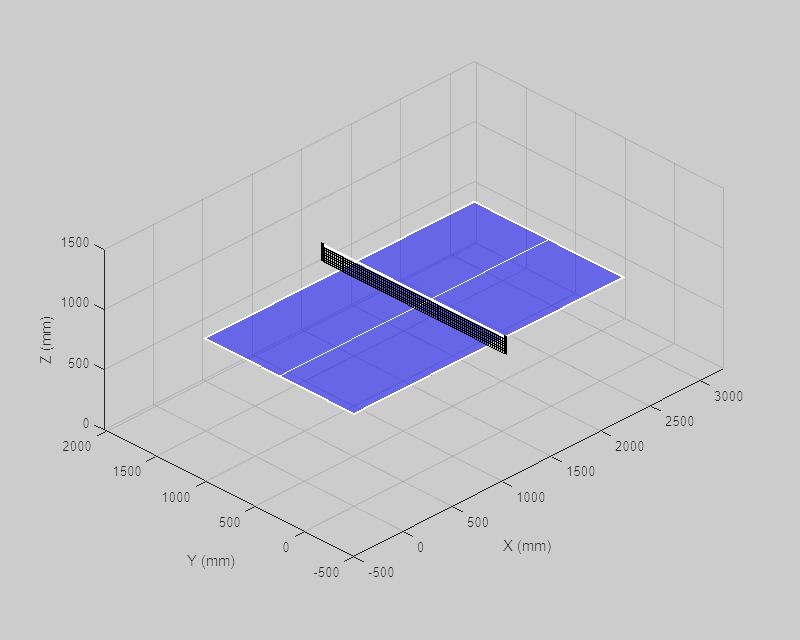

for k = 2:length(t)
    F = g*ball_mass*[0; 0; -1] - drag*v(:,k-1) + magnus*cross(omega(:,k-1),v(:,k-1));
    a(:,k) = F/ball_mass;
    v(:,k) = v(:,k-1) + a(:,k)*dt;
    x(:,k) = x(:,k-1) + v(:,k)*dt;
    tau = - rot_drag*omega(:,k-1);
    alpha(:,k) = tau/ball_rot_inertia;
    omega(:,k) = omega(:,k-1) + alpha(:,k)*dt;
    theta(:,k) = theta(:,k-1) + omega(:,k)*dt;
    % Bounce
    if((x(1,k)>0) && (x(1,k)<table_length) && (x(2,k)>0) && (x(2,k)<table_width) && x(3,k)< table_height+ball_radius)
        x(3,k) = table_height+ball_radius;
        delta_lin_rot = cross(omega(:,k),[0;0;ball_radius])-[v(1:2,k); 0];
        v(:,k) = v(:,k) + table_friction*delta_lin_rot;
        omega(:,k) = omega(:,k) + table_friction*cross(delta_lin_rot,[0;0;1])/ball_radius;
        v(3,k) = -table_restitution*v(3,k);
    end
    % Net Collision (to improve)
    if((x(1,k)>=table_length/2-ball_radius) && (x(1,k)<=table_length/2+ball_radius) &&...
       (x(2,k)>-net_extra) && (x(2,k)<table_width+net_extra) &&...
       (x(3,k)> table_height+ball_radius) && (x(3,k)< table_height+net_height+ball_radius))
        omega(:,k) = net_restitution*omega(:,k);
        v(1,k) = -net_restitution*v(1,k);
    end
    %
    if(animate == true && mod(k,plot_period) == 0) 
        plotTable(x(:,k),v(:,k),a(:,k),theta(:,k),omega(:,k),alpha(:,k), yaw, pitch)
        pause(0)
    end
end

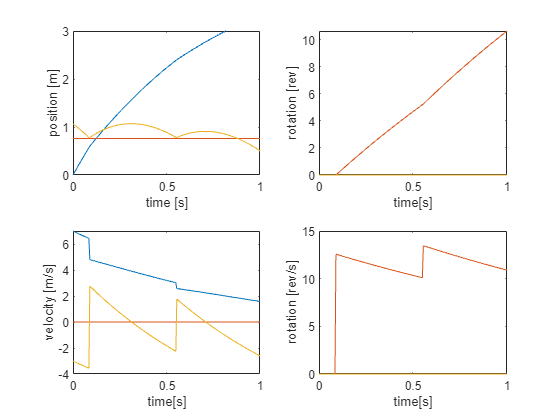

figure()
subplot(2,2,1)
plot(t,x/1000)
xlabel('time [s]')
ylabel('position [m]')
ylim([0,3])
subplot(2,2,3)
plot(t,v/1000)
xlabel('time[s]')
ylabel('velocity [m/s]')
subplot(2,2,2)
plot(t,theta/(2*pi))
xlabel('time[s]')
ylabel('rotation [rev]')
subplot(2,2,4)
plot(t,omega/(2*pi))
xlabel('time[s]')
ylabel('rotation [rev/s]')

function plotTable(x,v,a,theta,omega,alpha,yaw, pitch)
% Define the dimensions of the table tennis table
table_length = 2740;  % mm
table_width = 1525;   % mm
table_height = 760;   % mm

net_height = 152.5;   % mm
net_extra = 180;      % mm
% Plot the table surface
[X, Y] = meshgrid([0, table_length], [0, table_width]);
Z = ones(size(X)) * table_height;
surf(X, Y, Z, 'FaceColor', 'b', 'EdgeColor', 'none', 'FaceAlpha', 0.5);
hold on;
% Plot the white lines
[X, Y] = meshgrid([0, 20], [0, table_width]);
Z = ones(size(X)) * table_height+0.1;
surf(X, Y, Z, 'FaceColor', 'w', 'EdgeColor', 'none');
[X, Y] = meshgrid([table_length-20, table_length], [0, table_width]);
Z = ones(size(X)) * table_height+0.1;
surf(X, Y, Z, 'FaceColor', 'w', 'EdgeColor', 'none');
[X, Y] = meshgrid([0, table_length], [0, 20]);
Z = ones(size(X)) * table_height+0.1;
surf(X, Y, Z, 'FaceColor', 'w', 'EdgeColor', 'none');
[X, Y] = meshgrid([0, table_length], [table_width-20, table_width]);
Z = ones(size(X)) * table_height+0.1;
surf(X, Y, Z, 'FaceColor', 'w', 'EdgeColor', 'none');
[X, Y] = meshgrid([0, table_length], [table_width/2-5, table_width/2+5]);
Z = ones(size(X)) * table_height+0.1;
surf(X, Y, Z, 'FaceColor', 'w', 'EdgeColor', 'none');

% Plot the net
[Y, Z] = meshgrid([-net_extra+30, table_width+net_extra-30], [table_height+130, table_height+net_height]);
X = ones(size(Z)) * table_length/2;
surf(X, Y, Z, 'FaceColor', 'w', 'EdgeColor', 'none');
[Y, Z] = meshgrid([-net_extra, -net_extra+30], [table_height, table_height+net_height]);
X = ones(size(Z)) * table_length/2;
surf(X, Y, Z, 'FaceColor', 'k', 'EdgeColor', 'none');
[Y, Z] = meshgrid([table_width+net_extra-30, table_width+net_extra], [table_height, table_height+net_height]);
X = ones(size(Z)) * table_length/2;
surf(X, Y, Z, 'FaceColor', 'k', 'EdgeColor', 'none');
net_square_side = 20;
net_lines_v = -net_extra+30:net_square_side:table_width+net_extra-30;
net_lines_h = table_height:net_square_side:table_height+130;
for i = 1:length(net_lines_h)
    plot3(table_length/2*ones(1,2), [-net_extra+30, table_width+net_extra-30], [net_lines_h(i), net_lines_h(i)],'k','LineWidth',0.5)
end
for i = 1:length(net_lines_v)
    plot3(table_length/2*ones(1,2), [net_lines_v(i), net_lines_v(i)], [table_height, table_height+130],'k','LineWidth',0.5)
end

% Plot the ball
radius = 20.25;
[X, Y, Z] = sphere(25);
surf(X*radius + x(1), Y*radius + x(2), Z*radius + x(3), 'FaceColor', 'w', 'FaceAlpha', 1, 'EdgeColor','none');

% Plot the ball velocity and acceleration
quiver3(x(1),x(2),x(3),v(1),v(2),v(3),10/98,'LineWidth',2,'Color','g')
quiver3(x(1),x(2),x(3),a(1),a(2),a(3),1/49,'LineWidth',2,'Color','c')

% Plot the ball orientation, angular velocity, and angular acceleration
quiver3(x(1),x(2),x(3),omega(1),omega(2),omega(3),1,'LineWidth',2,'Color','r')
%quiver3(x(1),x(2),x(3),alpha(1),alpha(2),alpha(3),1,'LineWidth',2,'Color','m')

% Set plot properties
axis equal;
view([yaw pitch])
xlabel('X (mm)');
ylabel('Y (mm)');
zlabel('Z (mm)');
set(gcf, 'Color', [0.8, 0.8, 0.8]); % Set the color to a light gray
ax = gca;
ax.Color = 'none';
grid on;
xlim([-500, table_length + 500])
ylim([-500, table_width  + 500])
zlim([0, 1500])
hold off;
end